# Least Squares Support Vector Machines, Ex. 1

First set up the environment and load the LSSVM and SVM KU Leuven toolboxes by adding them to them path. Then set the seed for reproducible results.

rng(666)

## Two Gaussians

Two Gaussians with the same covariance matrix generate a dataset. Can we manually create something resembling an optimal classifier?

[X1, X2, Y1, Y2] = deal(randn(50, 2) + 1,  randn(51, 2) - 1, ones(50, 1), -ones(51, 1));
figure; hold on; plot(X1(:,1),X1(:,2), 'ro');  plot(X2(:,1),X2(:,2), 'bo'); hold off;

For binary classification, an optimal linear classifier classifies all of the data points correctly while being as far away from the points as possible. In this case, the data are not linearly separable, hence the first condition cannot be fulfilled. The linear classifier will have some inherent misclassification rate. The far-away-ness criterion is fulfilled by maximizing a margin around the line in which no points are present.

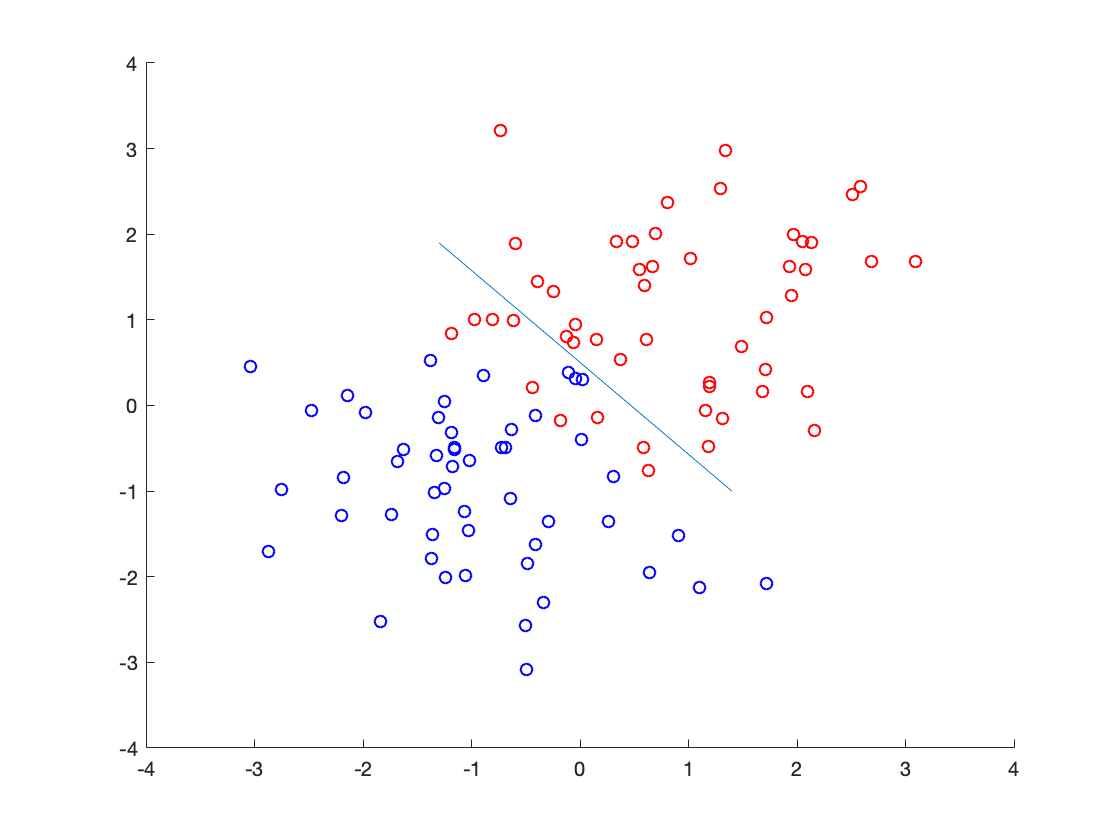

line([-1.3, 1.4], [1.9, -1])

## Support vector machine classifier

Exploring the applet at [https://cs.stanford.edu/people/karpathy/svmjs/demo/.](https://cs.stanford.edu/people/karpathy/svmjs/demo/.)

### What is a support vector?

A support vector is a data point that lies closest to some hyperplane that is able to separate classes with no or minimal misclassification. These points define the margin of the hyperplane. The objective of the hyperplane is to separate the classes while at the same time minimizing the size of this margin. The margin itself is defined by the fact that, beyond the support vectors which lie on the boundary of the margin, there are no data points inside of it.

### Linear kernel

Adding more points to the linear kernel adjusts the decision hyperplane slightly when adding outside the margin, and quite significantly when points are added outside the margin. How much a single point addition changes the boundary also depends on whether the point has been added close or far away from existing points of the same class.

The c parameter affects the number of support vectors used, and hence, the size of the margin. Below c = 1, the margin increases in size and the number of support vectors. This relationship is not so straightforward for larger values of c because the SVM converges around a number of vectors and stays there. This is in line with the fact that the c parameter is a measure of how much we want to avoid misclassification (how much the objective function takes misclassification into account).

### RBF kernel

The RBF kernel gives us a nonlinear boundary. Here, additions of points even close to existing ones can have large effects on classification far outside the region, since the RBF kernel has to extrapolate classification in some way for the entire areas outside the point clouds - hence, adding more points can shift the area to be classed as one class or the other.

Varying c has a large effect on how classification is done but generally results in either the collapse of the decision boundary to individual points of one class or maintaining the general shape of the boundary. Varying the sigma parameter has a large effect, smaller values make the boundary more granular, again to the point of collapsing it around the individual points of one class. On the other hand, making sigma very large makes the boundary more and more linear. This is consistent with the fact that sigma determines how much influence a single data point has on the decision boundary - taking into account only a few values in the case of high sigma thus makes the boundary linear.

### Comparison between linear and RBF in this applet

It seems that linear kernel works extremely well in the case of separable or mostly separable data. The RBF kernel is more suitable in case of nonseparable data, since the decision boundary is extremely flexible and granular.

## Least-squares support vector machine classifier

Load the iris dataset into Xtrain, Xtest, Ytrain, Ytest variables.

load iris.mat;

### Influence of hyperparameters and kernel parameters

#### Polynomial kernel

We can attempt modelling with polynomial kernels of different degrees, with $t=gam=1$.

gam = 1; degrees = {[1 1], [1 2], [1 3], [1 4], [1 5], [1 6]};
params = cellfun(@(degree) {Xtrain, Ytrain, 'c', gam, degree, 'poly_kernel'}, degrees, 'UniformOutput', false);
polyModels = cellfun(@(x) trainlssvm(x), params, 'UniformOutput',false);

Now evaluate on test set.

polyModelSim = cellfun(@(model) simlssvm({model.xtrain, model.ytrain, model.type, model.gam, model.kernel_pars, model.kernel_type}, {
model.alpha, model.b}, Xtest), polyModels,'UniformOutput', false);

We can now use evaluate the models by considering their misclasification rate.

polyPerf = cellfun(@(sim) [sum(sim ~= Ytest), sum(sim ~= Ytest)/length(Ytest)*100], polyModelSim, 'UniformOutput', false)

polyPerf = 1×6 cell array
    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}


The last three models have the same and lower misclassification rates.

We can also plot the decision boundary for one of them using the following function.

Start Plotting...

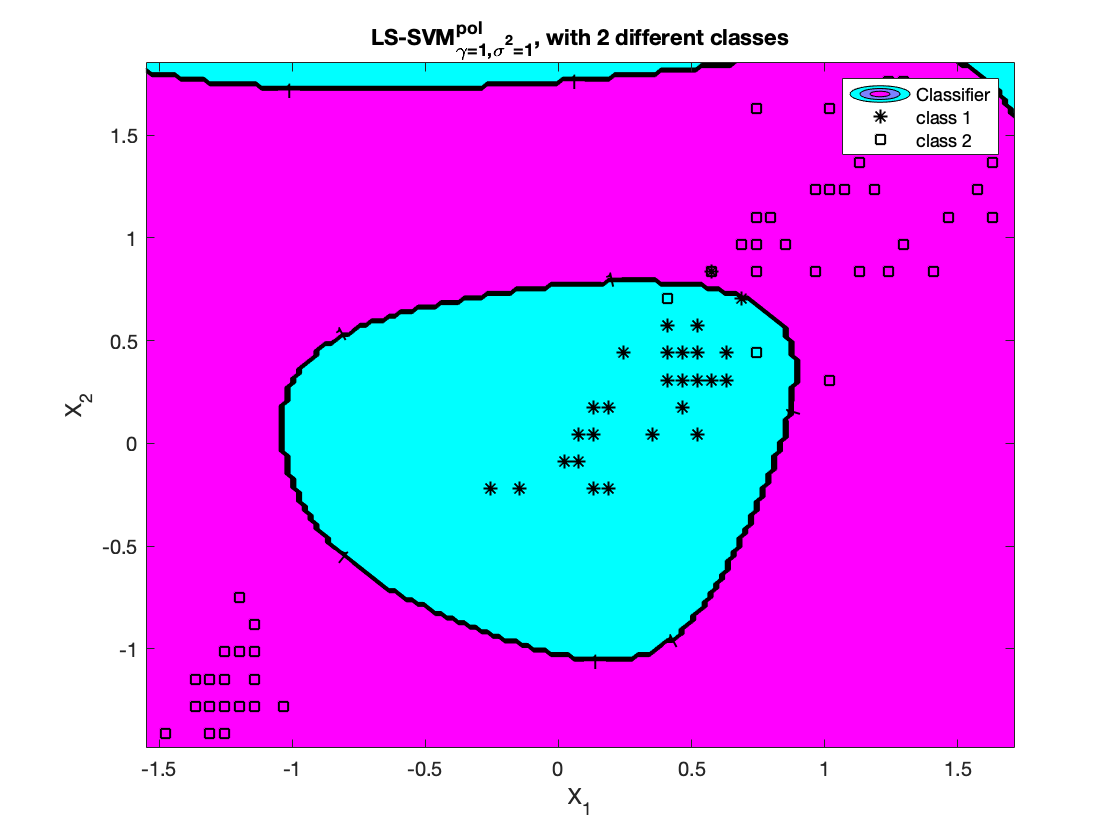

finished


ans = struct with fields:
           type: 'c'
          x_dim: 2
          y_dim: 1
        nb_data: 100
    kernel_type: 'poly_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [100×2 double]
         ytrain: [100×1 double]
       selector: [1×100 double]
            gam: 1
    kernel_pars: [1 5]
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'cc'
    pre_yscheme: 'b'
      pre_xmean: [-1.6209e-16 -3.1086e-16]
       pre_xstd: [1.0000 1.0000]
      pre_ymean: -1
       pre_ystd: 1
         status: 'trained'
        weights: []
          alpha: [100×1 double]
              b: -1.1437


plotterPoly = @(model) plotlssvm({model.xtrain, model.ytrain, model.type, model.gam, model.kernel_pars, model.kernel_type}, {
model.alpha, model.b});
plotterPoly(polyModels{5})

This decision boundary is quite reasonable.

#### RBF kernel

We can try a range of sigma parameters to find a well performing RBF kernel model.

gam = 1; sigmas = [0.001, 0.005, 0.01, 0.1, 1, 2, 10, 30, 50, 100];
RBFParams = arrayfun(@(sigma) {Xtrain, Ytrain, 'c', gam, sigma,'RBF_kernel'}, sigmas, 'UniformOutput', false);
RBFModels = cellfun(@(param) trainlssvm(param), RBFParams, 'UniformOutput',false);
RBFModelSim = cellfun(@(model) simlssvm({model.xtrain, model.ytrain, model.type, model.gam, model.kernel_pars, model.kernel_type}, {
model.alpha, model.b}, Xtest), RBFModels,'UniformOutput', false);
RBFPerf = cellfun(@(sim) [sum(sim ~= Ytest), sum(sim ~= Ytest)/length(Ytest)*100], RBFModelSim, 'UniformOutput', false)

RBFPerf = 1×10 cell array
    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}


It seems that none of the sigma choices perform particularly well on this dataset, but the middle ranges chosen are worse than the start and end values. Based on the plotted decision surfaces, a sigma value of 0.01 seems quite reasonable.

We can do the same comparison with a range of gam parameters.

sigma = 0.01; gams = [0.1, 1, 2, 5, 10, 30, 50, 100];
RBFParamsG = arrayfun(@(gamPar) {Xtrain, Ytrain, 'c', gamPar, sigma,'RBF_kernel'}, gams, 'UniformOutput', false);
RBFModelsG = cellfun(@(param) trainlssvm(param), RBFParamsG, 'UniformOutput', false);
RBFModelSimG = cellfun(@(model) simlssvm({model.xtrain, model.ytrain, model.type, model.gam, model.kernel_pars, model.kernel_type}, {
model.alpha, model.b}, Xtest), RBFModelsG, 'UniformOutput', false);
RBFPerfG = cellfun(@(sim) [sum(sim ~= Ytest), sum(sim ~= Ytest)/length(Ytest)*100], RBFModelSimG, 'UniformOutput', false)

RBFPerfG = 1×8 cell array
    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}    {1×2 double}


Let us plot one of the resulting models.

Start Plotting...

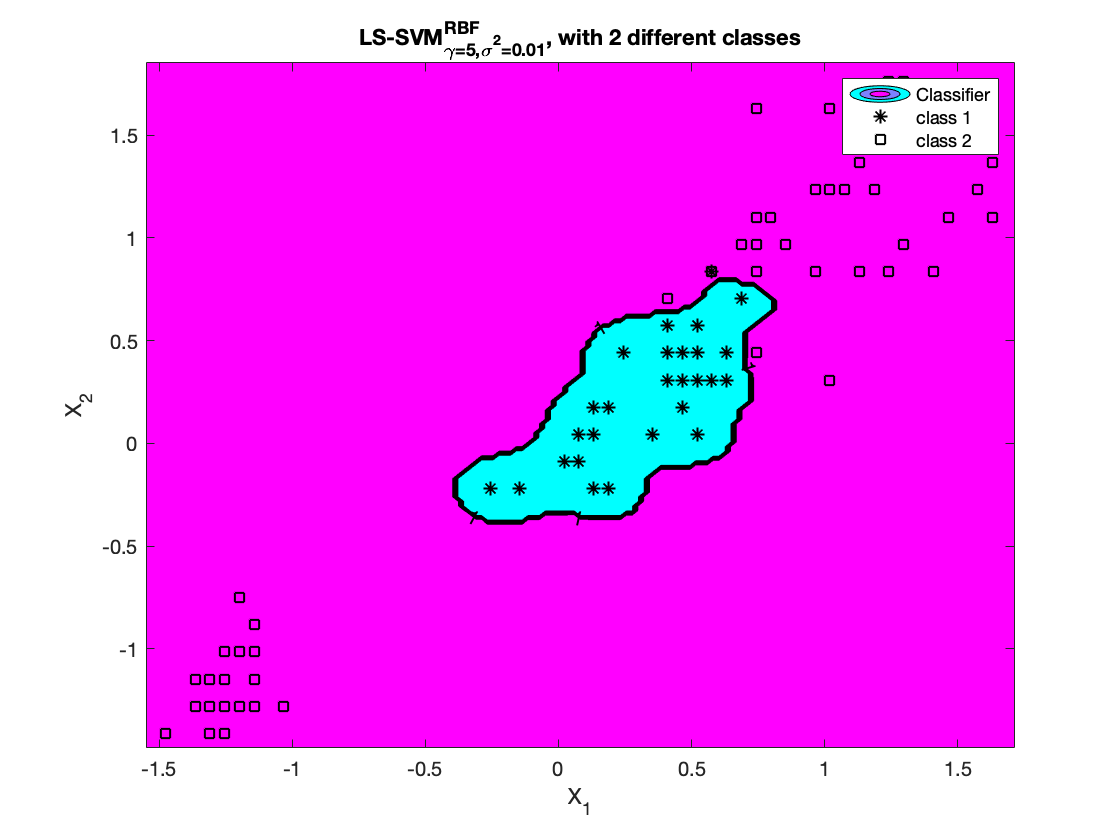

finished


ans = struct with fields:
           type: 'c'
          x_dim: 2
          y_dim: 1
        nb_data: 100
    kernel_type: 'RBF_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [100×2 double]
         ytrain: [100×1 double]
       selector: [1×100 double]
            gam: 5
    kernel_pars: 0.0100
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'cc'
    pre_yscheme: 'b'
      pre_xmean: [-1.6209e-16 -3.1086e-16]
       pre_xstd: [1.0000 1.0000]
      pre_ymean: -1
       pre_ystd: 1
         status: 'trained'
        weights: []
          alpha: [100×1 double]
              b: 0.3734


plotterRBF = @(model) plotlssvm({model.xtrain, model.ytrain, model.type, model.gam, model.kernel_pars, model.kernel_type}, {
model.alpha, model.b});
plotterRBF(RBFModelsG{4})

These results are broadly similar to the sample script provided.

### Tuning parameters using validation

We can look at the performance of different validaton methods in parameter tuning: random splits, k-fold and leave-one-out cross validaton. We will do this for the RBF kernel.

First we create the range of parameters to walk over.

gams = 10e-3:10e2:10e3; sigmas = 10e-3:10e2:10e3;
[sigmasMesh, gamsMesh] = meshgrid(sigmas, gams)

sigmasMesh = 	1.0e+03 *

    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.

gamsMesh = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000
    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000
    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000
    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000    7.0000
    8.0000    8.0000    8.0000    8.0000    8.0000    8.0000    8.0000    8.0000    8.0000    8.0000
    9.0000    9.0000    9.0000    9.0000    9.0000    9.0000    9.00

parameterSpace = num2cell([gamsMesh(:), sigmasMesh(:)], 2)

parameterSpace = 	1.0e+03 *

    0.0000    0.0000
    1.0000    0.0000
    2.0000    0.0000
    3.0000    0.0000
    4.0000    0.0000
    5.0000    0.0000
    6.0000    0.0000
    7.0000    0.0000
    8.0000    0.0000
    9.0000    0.0000


#### Random split

perf = rsplitvalidate ({ Xtrain , Ytrain , 'c', gam , sig2,'RBF kernel'}, 0.80 , 'misclass');

Error using rsplitvalidate (line 17)
rsplitvalidate: invalid kernel input.